stimulus = P(1).antennal_movement(:, startPt:stopPt);
raster = P(1).raster(:, startPt:stopPt);
window = 0.05;
fs = P.fs;
% stim_patterns = extract_stim_patterns(stimulus,raster, window, fs);
stim_patterns = getIsolatedSTE(stimulus, raster, window, fs);

STA = mean(stim_patterns,1);


sigma = 3e-3*fs; %3 ms
lmin  = 1e-4*fs; % 0.1 ms
step = 1e-4*fs;


err = 1;
while (err > 1e-11)
    err
    shift_vals = (lmin:step:sigma);
    
    % stim_patterns_cov_mat = cov(stim_patterns);
    
    mean_waveform = mean(stim_patterns,1);
%     plot(mean_waveform); title(err);
    
    shift_time = [];
    
    
    for stim_pattern_idx = 1:size(stim_patterns,1)
        
        distance = zeros(1, length(shift_vals));
        for shift_iter = 1:length(shift_vals)
            
            %round(shift_vals(shift_iter)*fs)
            stim_pattern_shifted = circshift(stim_patterns(stim_pattern_idx,:), round(shift_vals(shift_iter)*fs));
            t_shift = shift_vals(shift_iter);
            
            residual_waveform = stim_pattern_shifted - mean_waveform;
            distance(shift_iter) = 0.5*((residual_waveform*stim_patterns_cov_mat*residual_waveform') + (t_shift/sigma)^2);
            
        end
        
        [~,idx] = min(distance);
        shift_time(stim_pattern_idx) = shift_vals(idx);
        
    end
    
    stim_patterns_prev = stim_patterns;
%     stim_patterns = [];
    %     stim_patterns = realign_patterns(stim_patterns, shift_time, fs);
    for pattern_idx = 1:length(shift_time)
        shift_by_samples = round(shift_time(pattern_idx)*fs);
        shifted_stim_patterns = circshift(stim_patterns, shift_by_samples);
    end
    sigma = var(shift_time);
    stim_patterns = shifted_stim_patterns;
    err = (mean(var(stim_patterns_prev,0,1))-mean(var(shifted_stim_patterns,0,1)))/mean(var(stim_patterns_prev,0,1));
    err
    
    dejittered_STA = mean(shifted_stim_patterns, 1);
end

err = 1

err = 0

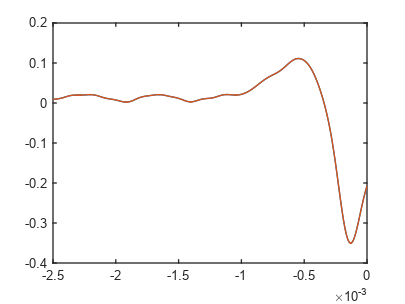


figure;

% t=-(window*1000):(1000/fs):(window*1000); %in ms
t = linspace(-window*1000/fs, 0, length(dejittered_STA));
plot(t, dejittered_STA);
hold on;

plot(t,STA);